# **Neutral faces *****vs***** Smiling faces**

#### **------------------------------------------------------------------------------------------------------------------------------------**

#### Face Data

#### **------------------------------------------------------------------------------------------------------------------------------------**

data = load('data.mat'); 
% extracting 'face' array from data. 200 subjects; 3 images per subject.
face = data.face; % 24x21x600
% splitting face array into three parts.
face_neutral = face(:,:,1:3:end); %starting from 1st image, picking every 3rd image % 24x21x200
face_exp = face(:,:,2:3:end); %starting from 2nd image, picking every 3rd image % 24x21x200
face_illum = face(:,:,3:3:end); %starting from 2nd image, picking every 3rd image % 24x21x200

#### **------------------------------------------------------------------------------------------------------------------------------------**

#### Pre-Processing

#### **------------------------------------------------------------------------------------------------------------------------------------**

1. Reshaping both neutral and smiley/exp matrices from 24x21x200 to 200x504; 

then we combine them to create array C [400x504] for further processing.

% Two classes: Neutral o_o and Smiley :)
% First, we convert both 24x21x200 class matrices 
%       into 200x504 matrices (each image as a row vector)
[dr, dc, n] = size(face_neutral); % NOTE: same size as face_exp
C1 = zeros(n,dr*dc); % Class 1: Neutral
C2 = zeros(n,dr*dc); % Class 2: Smiley
for i = 1:n
    rvn = face_neutral(:,:,i);
    C1(i,:) = rvn(:)';         % rvn(:)' is the row vector form of each neutral image
    rvs = face_exp(:,:,i);
    C2(i,:) = rvs(:)';         % rvs(:)' is the row vector form of each smiley image
end
C = [C1;C2]; % 400x504 (first 200 rows are neutral and the next 200 rows are smiley) 

2. Performing **Principal Component Analysis** to reduce the number of dimensions from 504 to nPCA dimensions

creating a projected array Y [400xnPCA] from C [400x504] 

% PCA
[U,Sig,V] = svd(C','econ');  % economy-size decomposition of C
nPCA = 50 % number of principal components

nPCA = 50

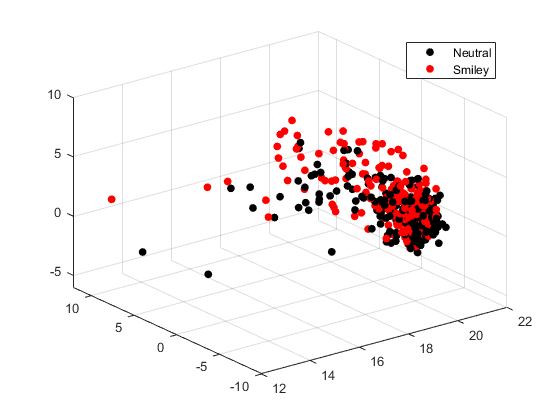

% project to nPCA-dimension space
Y = C*U(:,1:nPCA); % 400xnPCA (projected data)
%-----------------------------------------------------------------
% visualize Y in three dimensions (first three columns)
figure; hold on; grid;
% neutral faces
plot3(Y(1:n,1),Y(1:n,2),Y(1:n,3),'.','MarkerSize',20,'color','k'...
    ,'DisplayName','Neutral');
% smiling faces
plot3(Y(n+1:end,1),Y(n+1:end,2),Y(n+1:end,3),'.','MarkerSize',20,'color','r'...
    ,'DisplayName','Smiley');
view(3);
hold off;
legend('Location','northeast');

#### **------------------------------------------------------------------------------------------------------------------------------------**

#### Test/Train Split

#### **------------------------------------------------------------------------------------------------------------------------------------**

Total images: 400 || Class1: 200 & Class2: 200

Training-set to have first '**k**' rows from each class. Rest go into the testing-set.  

training-set size [2k by nPCA] ; testing-set size [2(n-k) by nPCA]  || where 'n' is 200 (class size)

k = 175;    % split size; 'k' has to be between 0 and 200
fprintf('Split %d/%d for each class\n',k,n-k);

Split 175/25 for each class


% training set (first k rows -> neutral | next k rows -> smiley)
Y_train = [Y(1:k,:);Y(n+1:n+k,:)];  % 2*k by nPCA
% testing set (first n-k rows -> neutral | next n-k rows -> smiley)
Y_test = [Y(k+1:n,:);Y(n+k+1:2*n,:)]; % 2*(n-k) by nPCA

#### **------------------------------------------------------------------------------------------------------------------------------------**

#### Classification

#### **------------------------------------------------------------------------------------------------------------------------------------**

**I.  Bayes' Classifier**

1. Estimate the means for each class. || mu1 and mu2

    Split the projected training data (Y_train) into Y1 and Y2, one for each class. 

Y1 = Y_train(1:k,:);    % training data of neutral class
Y2 = Y_train(k+1:end,:);  % training data of smiley class
mu1 = mean(Y1,1);   % column-mean of Y1
mu2 = mean(Y2,1);   % column-mean of Y2
% distance between the means
fprintf('distance between the means = %d\n', norm(mu1-mu2));

distance between the means = 3.265032e+00


2. Estimate the covariance matrices for each class. || S1 and S2

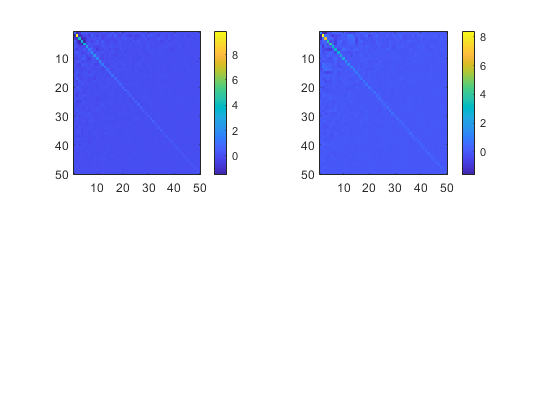

Y1c = Y1-ones(k,1)*mu1;   % center the data for class 1
Y2c = Y2-ones(k,1)*mu2;   % center the data for class 2
S1 = (Y1c'*Y1c)/k;        % covariance matrix for class 1 
S2 = (Y2c'*Y2c)/k;        % covariance matrix for class 2
%--------------------------------------------------------------------
% visualizing the covariance matrices to compare them
% we see that the matrices look more or less similar but not identical
% The root of the highest value for neutral matrices is more than the
% root of the highest value of smiley faces.
figure; grid;
subplot(2,2,1); 
imagesc(S1);
colorbar;
subplot(2,2,2);
imagesc(S2);
colorbar;

3. Define discriminant function g(x) for N(mu1,S1) and N(mu2,S2)

    Decision rule: If g(x)>0, decide neutral face; if g(x)<0, decide smiley face

    Note: 'Equal Priors', i.e. P(w1) = P(w2), since [ #_of_neutral_faces = #_of_smiley_faces = k ]

iS1 = inv(S1); % inverse of the covariance matrix
iS2 = inv(S2);
mu1 = mu1'; % row vector to column vector
mu2 = mu2'; 
w0 = 0.5*(log(det(S2)/det(S1))) - 0.5*(mu1'*iS1*mu1 - mu2'*iS2*mu2);
g = @(x)-0.5*x'*(iS1-iS2)*x + x'*(iS1*mu1 - iS2*mu2) + w0;

4. Classifying the test set 

% test data 1 (actual value: Neutral)
nLabel = zeros(n-k,1);      % predictions
Y3 = Y_test(1:n-k,:);       % First half rows [neutral]
for j = 1:(n-k)
    y = Y3(j,:)';
    nLabel(j) = sign(g(y));
end
iplus_tp = find(nLabel>0);  % predicted Neutral
iminus_fn = find(nLabel<0); % predicted Smiley
fprintf('Neutral faces: correctly classified = %d, misclassified = %d\n',...
         length(iplus_tp), length(iminus_fn));

Neutral faces: correctly classified = 21, misclassified = 4



% test data 2 (actual value: Smiley)
sLabel = zeros(n-k,1);      % predictions
Y4 = Y_test(n-k+1:end,:);   % Next half rows [smiley]
for j = 1:(n-k)
    y = Y4(j,:)';
    sLabel(j) = sign(g(y));
end
iplus_fp = find(sLabel>0);  % predicted Neutral
iminus_tn = find(sLabel<0); % predicted Smiley
fprintf('Smiley Faces: misclassified = %d, correctly classified = %d\n',...
         length(iplus_fp), length(iminus_tn));

Smiley Faces: misclassified = 2, correctly classified = 23



accuracy = (length(iplus_tp) + length(iminus_tn))/size(Y_test,1);
fprintf('Accuracy = %f\n', accuracy);

Accuracy = 0.880000


*Displaying the misclassfied images*

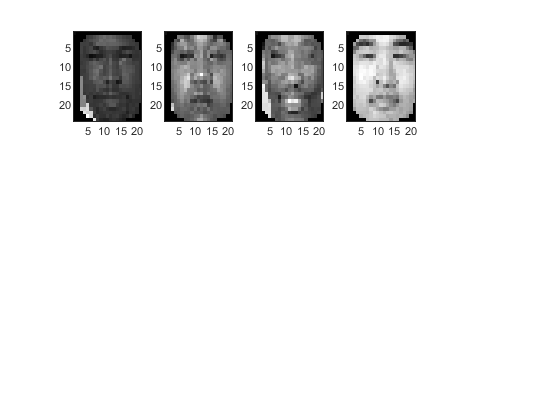

% Neutral faces misclassified as Smiley
iminus_fn;
figure;
colormap gray
for j = 1:15
    if(j<=length(iminus_fn))
        subplot(3,5,j);
        imagesc(face_neutral(:,:,k+iminus_fn(j))); 
    end
end

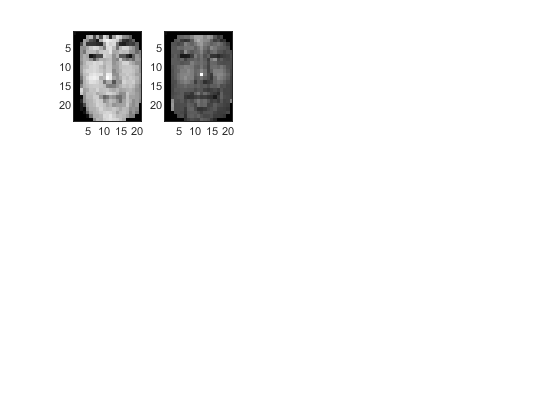

% Smiley faces misclassified as Neutral
iplus_fp;
figure;
colormap gray
for j = 1:15
    if(j<=length(iplus_fp))
        subplot(3,5,j);
        imagesc(face_exp(:,:,k+iplus_fp(j)));
    end
end

**II.  k-NN Classifier**

nPCA dimensional space | Distance metric: Euclidean 

Each row in the training set is an example/instance. Each row in the test set is an observation that needs to be classified.

1. Finding Euclidean distance from each observation to each of the training data example/instance. 

% Splitting the test data into two, based on their 'actual' labels.
Y3 = Y_test(1:n-k,:);       % First half rows [neutral]
Y4 = Y_test(n-k+1:end,:);   % Next half rows [smiley]
D1 = zeros(2*k,n-k);         
D2 = zeros(2*k,n-k);        
for i = 1:(n-k)
    % distance from each obs in Y3 to the training examples (total k distances for each obs) 
    D1(:,i) = sqrt(sum((Y_train-Y3(i,:)).*(Y_train-Y3(i,:)),2));
    % distance from each obs in Y4 to the training examples (total k distances for each obs)
    D2(:,i) = sqrt(sum((Y_train-Y4(i,:)).*(Y_train-Y4(i,:)),2));
end
D1;
D2;

2. Sorting the distances and and retrieving nearest neighbors. 

    Labelling each obs in Y3 and Y4 accordingly.

kNN = 11; % number of nearest neighbors to be considered
fprintf('Number of nearest neighbors to be considered: %d\n',kNN)

Number of nearest neighbors to be considered: 11


label_N = zeros(n-k,1);
label_S = zeros(n-k,1);
for i = 1:(n-k)
    % neutral test cases 
    [dsort,isort] = sort(D1(:,i),'ascend');
    k_near_neigh = isort(1:kNN);                    
    neutral_neigh = find(k_near_neigh<(k+1));
    smiley_neigh = find(k_near_neigh>k);
    if (length(neutral_neigh)>length(smiley_neigh))
        label_N(i) = 1;         % if classified as Neutral
    else 
        i
        label_N(i) = -1;        % if classified as Smiley
    end
    % smiley test cases 
    [dsort,isort] = sort(D2(:,i),'ascend');
    k_near_neigh = isort(1:kNN);
    neutral_neigh = find(k_near_neigh<(k+1));
    smiley_neigh = find(k_near_neigh>k);
    if (length(neutral_neigh)<length(smiley_neigh))
        label_S(i) = 1;         % if classified as Smiley
    else 
        label_S(i) = -1;        % if classified as Neutral
    end
end
tp = length(find(label_N>0));   % correctly classified Neutral faces
fn = length(find(label_N<0));   % misclassified Neutral faces
tn = length(find(label_S>0));   % correctly classified Smiley faces
fp = length(find(label_S<0));   % misclassified Smiley faces
fprintf('Neutral faces: correctly classified = %d, misclassified = %d\n',tp,fn);

Neutral faces: correctly classified = 25, misclassified = 0


fprintf('Smiley Faces: misclassified = %d, correctly classified = %d\n',fp,tn);

Smiley Faces: misclassified = 6, correctly classified = 19


accuracy = ((tp + tn)/size(Y_test,1));
fprintf('Accuracy = %f\n', accuracy);

Accuracy = 0.880000


*Displaying the misclassfied images*

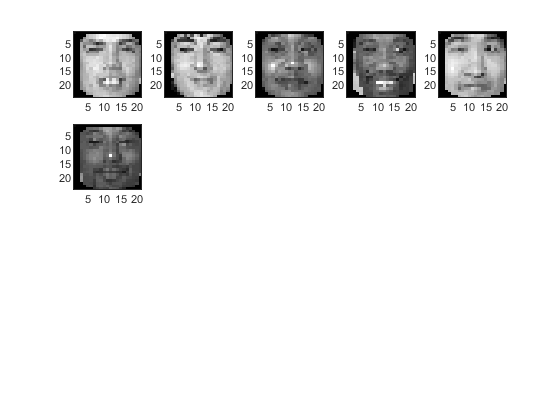

% Neutral faces misclassified as Smiley
idx_fn = find(label_N<0);
fn;
figure;
colormap gray
for j = 1:20
    if(j<=fn)
        subplot(4,5,j);
        imagesc(face_neutral(:,:,k+idx_fn(j))); 
    end
end
% Smiley faces misclassified as Neutral
idx_fp = find(label_S<0);
fp;
figure;
colormap gray
for j = 1:20
    if(j<=fp)
        subplot(4,5,j);
        imagesc(face_exp(:,:,k+idx_fp(j)));
    end
end